#  EEE3548 Exercise #2 Basic Image Processing (PSF, OTF)

## [23.04.07] [ImHyeonJeong]

#### In this exercise, we will review the basic concepts in linear imaging systems.

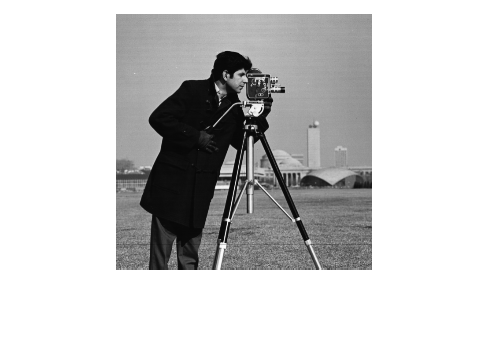

testImg = imread('cameraman.tif');
imshow(testImg);

#### Q1. Create a Line impuse image $\delta(x)$

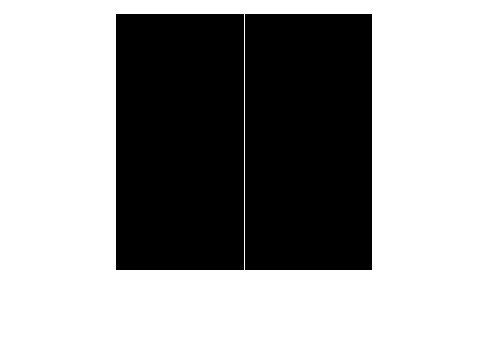

[N, M] = size(testImg);
[X, Y] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);

LineImpulse = zeros(N, M);
LineImpulse(X==0) = 1;

imshow(LineImpulse);

#### Q2. Create line impulse at angle $-\pi/3$ at distance of 10 pixels from the center. 

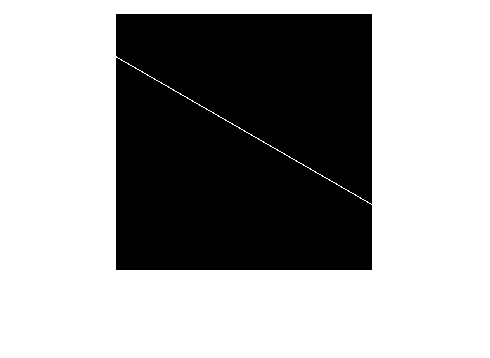

angle = -pi/3; distance = 10;

LineImpulse = zeros(N, M);
LineImpulse(round(X*cos(angle)+Y*sin(angle))==distance) = 1;

imshow(LineImpulse);

#### Q3. Get the pixel values of the test image along the line in Q2 and plot it

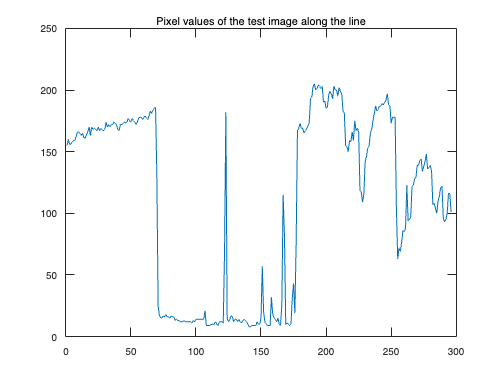

PixelValue = testImg(round(X*cos(angle)+Y*sin(angle))==distance);

figure; plot(PixelValue); title('Pixel values of the test image along the line');

## Point spread function

The output image of a linear shift-invariant image system is the result of the convolution between the input and the impulse response, or the point spread function.


$$g(x,y)=h(x,y)\ast h(x,y)$$


Now, let's define a sample 2D PSF. For example, let's imagine a linear shift-invariant imaging system whose PSF is a 2D gaussian. 2D Gaussian is defined as


$$h(x,y)=\frac{1}{2\pi \sigma^2}e^{-(x^2+y^2)/2\sigma^2}$$


#### Q4. Implement a 2D gaussian PSF with sigma of 2 pixels. 

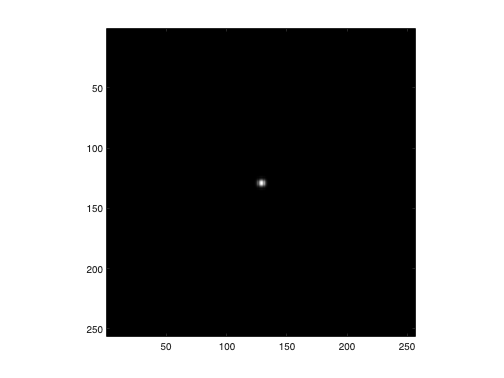

[N, M] = size(testImg);
[X, Y] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);

sigma = 2;
psf = 1/(2*pi*sigma^2)*exp(-(X.^2+Y.^2)/(2*sigma^2));

figure; imagesc(psf); colormap gray; axis image;

#### Q5. In the previous exercise, we implemented 1d convolution using FFT. Here, we will implement fast 2D convolution using 2d FFTs. Use fft2, ifft2, fftshifts/ifftshifts wisely to implement fast 2D convolution (See [https://kr.mathworks.com/help/matlab/ref/fft2.html](https://kr.mathworks.com/help/matlab/ref/fft2.html) for details). Check your results by convolving the cameraman with the gaussian PSF.

Hint : You can use [padarray](https://kr.mathworks.com/help/images/ref/padarray.html) to match the sizes of the psf and the image.

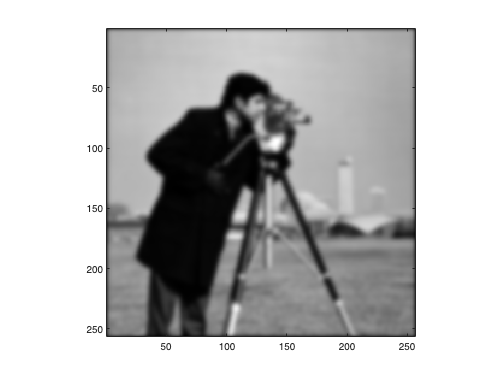

blurred = fftconv2d(testImg, psf);

figure; imagesc(blurred); colormap gray; axis image;

#### Q6. MATLAB has built-in 2D convolution.([https://kr.mathworks.com/help/matlab/ref/conv2.html](https://kr.mathworks.com/help/matlab/ref/conv2.html)) Compare your results with the built-in 2d conv. How well is your fftconv doing?

blurred_2 = conv2(testImg, psf, 'same');

figure; imagesc(blurred_2); colormap gray; axis image;

#### Q7. Take the Fourier transform of the cameraman image and plot its spectrum. The spectrum needs to be plotted in log in order to view all frequency components.

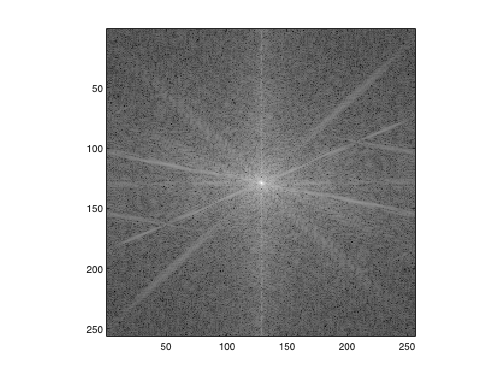

F_img = fft2(testImg);

figure; imagesc(log(abs(fftshift(F_img)))); colormap gray; axis image;

#### Q8. Now try the FT of the test image convolved with the 2D gaussian PSF. How does it differ from the previous result? What does it mean

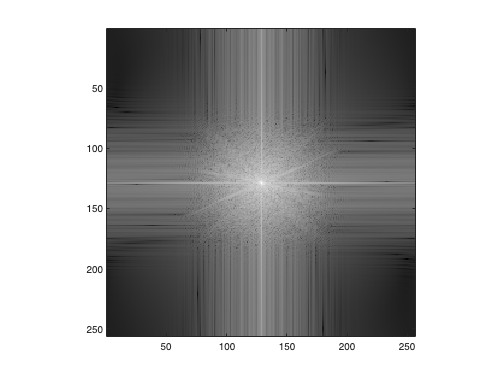

F_blurred = fft2(blurred);

figure; imagesc(log(abs(fftshift(F_blurred)))); colormap gray; axis image;

**Answer **: 가운데 영역은 비슷하게 생겼지만, 바깥쪽 영역의 패턴들이 바뀐 것으로 보아 샘플링으로 인해 blurring이 발생하여 바깥쪽 정보들(spatial frequency가 높은 성분, 즉 세밀한 features)이 사라졌음을 알 수 있다.

#### Q9. Plot the magnitude spectrum of this imaging system and describe how this system transforms your image in the spatial frequency domain. 

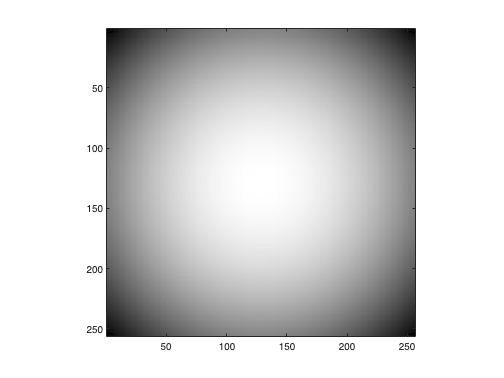

F_psf = fft2(fftshift(psf));

figure; imagesc(log(abs(fftshift(F_psf)))); colormap gray; axis image;

**Answer **: 낮은 주파수 성분들을 점점 없애는 low pass filter 역할을 수행한다. 

## Optical Transfer Function

Point spread function is a Fourier transform of the transfer function of the imaging system. An imaging system, for example a camera, behaves like an ideal low-pass filter with a fixed cut-off frequency. An ideal low pass filter in the Fourier domain can be written as;


$$H(k_x, k_y) = \begin{cases}1 \text{, for } k_x^2 + k_y^2 \leq k_c^2 \\ 0 \text{, for } k_x^2 + k_y^2 > k_c^2 \end{cases}$$


In this problem, we will design a transfer function of an ideal camera, whose cut-off frequency is $k_c$ = 8 cycles per mm. To compute the spatial frequency values, let's assume that a pixel is 0.01mm.

#### Q10. Create an image of sinusoidal stripes with fixed spatial frequencies of  3, 10, 20 cycles per mm in different directions (your choice). To evaluate spatial frequency in units of cycles per mm, we will assign a physical size (0.01 mm) to a pixel.

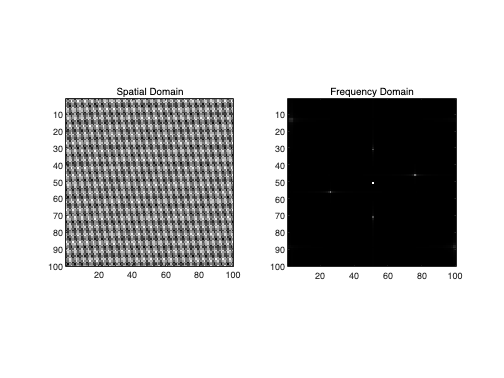

N = 100;
psize = 0.01; %mm

kx = linspace(-1/2, 1/2, N)/psize;
ky = linspace(-1/2, 1/2, N)/psize;
[X, Y] = meshgrid(kx, ky);

fx1 = 3*cos(pi/3); fy1 = 3*sin(pi/3);
fx2 = 10*cos(pi/6); fy2 = 10*sin(pi/6);
fx3 = 20*cos(pi/2); fy3 = 20*sin(pi/2);

sinstr = 3*ones(N,N) + 2*sin(2*pi*(fx1*X+fy1*Y)) + 3*sin(2*pi*(fx2*X+fy2*Y)) + 2*sin(2*pi*(fx3*X+fy3*Y));
F_sinstr = fft2(sinstr);
spectrum = abs(fftshift(F_sinstr));

figure;
subplot(121); imagesc(sinstr); colormap gray; axis image; title('Spatial Domain');
subplot(122); imagesc(spectrum); colormap gray; axis image; title('Frequency Domain');

#### Q11. Design the ideal OTF and see what the output image should be when the input is the image computed in Q10. How does the result look?

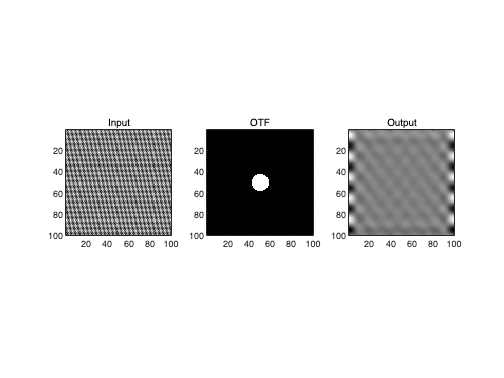

N = length(sinstr);
psize = 0.01; %mm

kx = linspace(-1/2, 1/2, N)/psize;
ky = linspace(-1/2, 1/2, N)/psize;
[KX, KY] = meshgrid(kx, ky);
kc = 8;

OTF = ((KX.^2+KY.^2) < kc.^2);

% Ideal Low Pass Filtering
Out = OTF.*fftshift(F_sinstr); % frequency domain
out = ifft2(Out); % spatial domain

figure;
subplot(131); imagesc(sinstr); colormap gray; axis image; title('Input');
subplot(132); imagesc(OTF); colormap gray; axis image; title('OTF');
subplot(133); imagesc(abs(out)); colormap gray; axis image; title('Output');

#### Q12. Now, use the same OTF to compute the output image when the input object is the cameraman image.

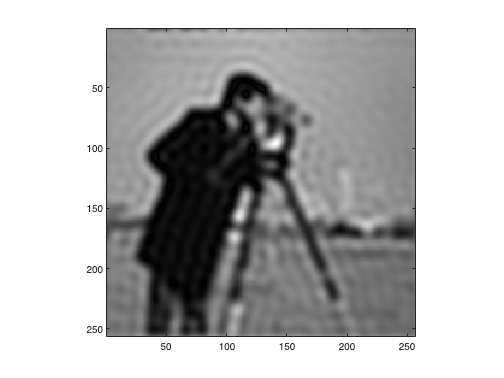

N = length(testImg);
psize = 0.01; %mm

kx = linspace(-1/2, 1/2, N)/psize;
ky = linspace(-1/2, 1/2, N)/psize;
[KX, KY] = meshgrid(kx, ky);
kc = 8;

OTF = ((KX.^2+KY.^2) < kc.^2);

% Ideal Low Pass Filtering
Out = OTF.*fftshift(fft2(testImg)); % frequency domain
out = ifft2(Out); % spatial domain

figure; imagesc(abs(out)); colormap gray; axis image; % 링잉 발생

### Discussion

Gaussian filtering과 다르게 ILPF 결과에서는 링잉 현상 발생

jinc funtion 형태의 그래프에 존재하는 리플들이 PSF이기 때문에 이것으로 convolution을 하면 edge가 심한 부분에서는 리플들이 그대로 나타나게 됨 → 링잉

# Functions

function x = fftconv2d(image, psf)
    % Zero padding for preventing aliasing
    img_pad = padarray(image, [length(image)/2 length(image)/2], 0, 'both');
    filter_pad = padarray(psf, [length(image)/2 length(image)/2], 0, 'both');

    % Convolution by fft
    out = ifftshift(ifft2(fft2(img_pad).*fft2(filter_pad)));

    % remove padding for original size
    target_size = [length(image) length(image)];
    window = centerCropWindow2d(size(out), target_size);
    x = imcrop(out, window);
end